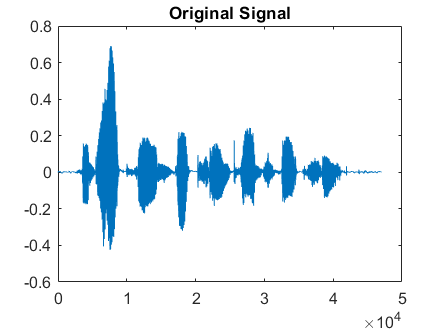

clear, clc, close all

[x, Fs] = audioread('SignalHW2.wav');

plot(x); title('Original Signal'); 

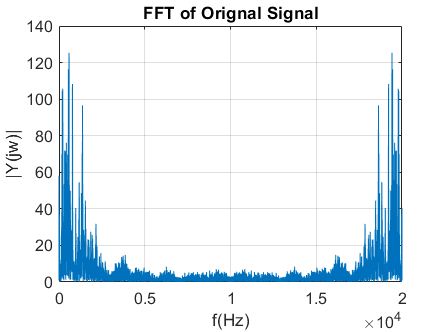

Len_y=length(x); p=abs(fft(x)); f=(Fs/Len_y)*(1:Len_y); figure; plot(f,p);
title('FFT of Orignal Signal'); ylabel('|Y(jw)|'); xlabel('f(Hz)'); grid;

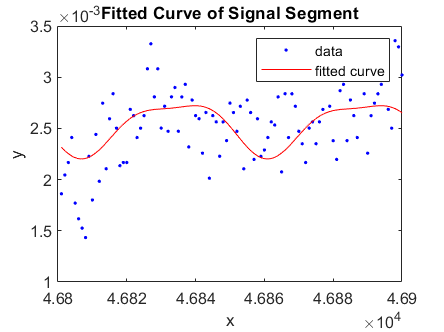


vector = [];

incrementCount = 100;
% 1st Segment
for n = 1:floor(length(x) / incrementCount)
    incrementCount = 100*n;
    initialValue = incrementCount-99;
    x1 = x(initialValue:incrementCount);
    y = [initialValue:incrementCount]';
    f = fit(y,x1,'fourier2');
    for b = initialValue : incrementCount
    vector(end+1) = f(b);
    end
    plot(f, y, x1); title('Fitted Curve of Signal Segment')

end

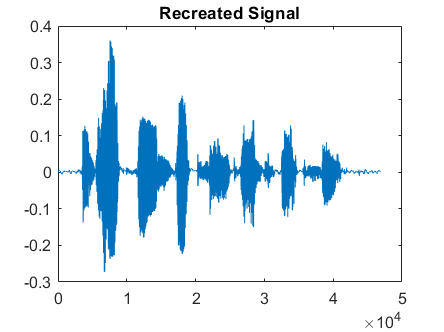


sound(x, Fs)
pause(5);
plot(vector); title('Recreated Signal'); 

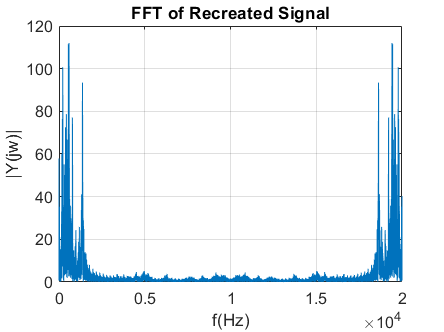

sound(vector, Fs)

y = vector;
Len_y=length(y); p=abs(fft(y)); f=(Fs/Len_y)*(1:Len_y); figure; plot(f,p);
title('FFT of Recreated Signal'); ylabel('|Y(jw)|'); xlabel('f(Hz)'); grid;